# Equacions diferencials - Pràctica 33

## 

syms y(t)
eqn = diff(y,t) == 1+t-y;
cond = y(0) == 1;
ySol = dsolve(eqn,cond);

## **Solucions aproximades numèricament**

-  `Mètode d'Euler prenent h = 0.1, h = 0.05`

a = 0;
alpha = 1; %y(a) = alpha
b = 1;     %y(b) = ..     
h = 0.1;
f = @(t,y)(1+t-y);
[w] = Euler(f,a,b,h,alpha);
disp([a:h:b;w]')

         0    1.0000
    0.1000    1.0000
    0.2000    1.0100
    0.3000    1.0290
    0.4000    1.0561
    0.5000    1.0905
    0.6000    1.1314
    0.7000    1.1783
    0.8000    1.2305
    0.9000    1.2874
    1.0000    1.3487



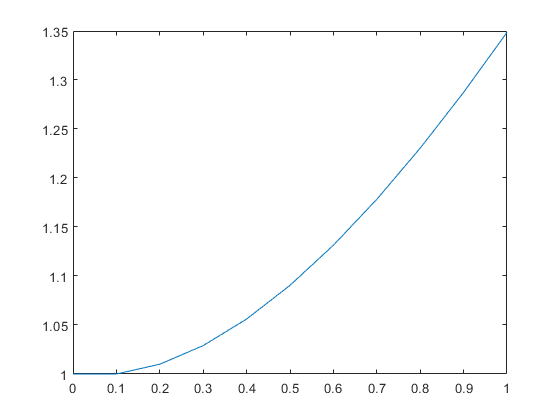

x = a:h:b;
plot(x,w);

plot(x,ySol(x));

Array indices must be positive integers or logical values.

Error in sym/subsref (line 898)
            R_tilde = builtin('subsref',L_tilde,Idx);

legend('h=0.1', 'solució analítica', 'location','bestoutside');
title('mètode Euler')

- `Mètode d'Euler modificat`

a = 0;
alpha = 1; %y(a) = alpha
b = 1;     %y(b) = ..     
h = 0.1;
f = @(t,y)(1+t-y);
[w] = Euler(f,a,b,h,alpha);
disp([a:h:b;w]')
x = a:h:b;
plot(x,w);
plot(x,ySol(x));
legend('h=0.1', 'solució analítica', 'location','bestoutside');
title('mètode Euler')

- Error Local

errorlocal = YM2-ySOL(x2)

- Error global

errorGlobal = YM2(end) - double(ySol(1));

- Error Local

errorlocal = YM2-ySOL(x2)

- Error global

errorGlobal = YM2(end) - double(ySol(1));

- Mètode de Heun